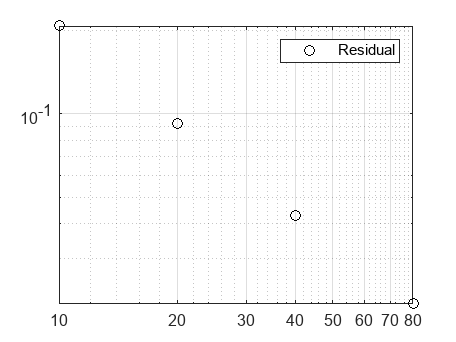

clc, clear; close all;

% given function
f = @(x) sin(x).^2;

%discretize - mesh
delta = [pi/10 pi/20 pi/40 pi/80];
x = pi/3;
mesh = pi./delta;

exactDiff = @(x) 2.*cos(x).*sin(x);
dfdx = exactDiff(x);

% First order forward
diffF = (f(x+delta)-f(x))./delta;
residual = abs(dfdx-diffF);

loglog(mesh,residual,'ko')
grid on
legend('Residual')